L_set = 150;        % lux (example for mushrooms)
L_measured = 90;

eL = L_set - L_measured;



fisL = mamfis('Name','LEDController');

fisL = addInput(fisL,[-200 200],'Name','LightError');

fisL = addMF(fisL,'LightError','trimf',[-200 -200 0],'Name','Bright');
fisL = addMF(fisL,'LightError','trimf',[-50 0 50],'Name','OK');
fisL = addMF(fisL,'LightError','trimf',[0 200 200],'Name','Dark');

fisL = addOutput(fisL,[0 100],'Name','LEDLevel');

fisL = addMF(fisL,'LEDLevel','trimf',[0 0 20],'Name','OFF');
fisL = addMF(fisL,'LEDLevel','trimf',[15 35 55],'Name','LOW');
fisL = addMF(fisL,'LEDLevel','trimf',[50 70 90],'Name','MEDIUM');
fisL = addMF(fisL,'LEDLevel','trimf',[80 100 100],'Name','HIGH');

rulesL = [
    "IF LightError IS Bright THEN LEDLevel IS OFF"
    "IF LightError IS OK THEN LEDLevel IS LOW"
    "IF LightError IS Dark THEN LEDLevel IS MEDIUM"
];

fisL = addRule(fisL, rulesL);


LED_output = evalfis(fisL, eL)

LED_output = 70.0000

LED_pwm = round((LED_output/100)*255)

LED_pwm = 179

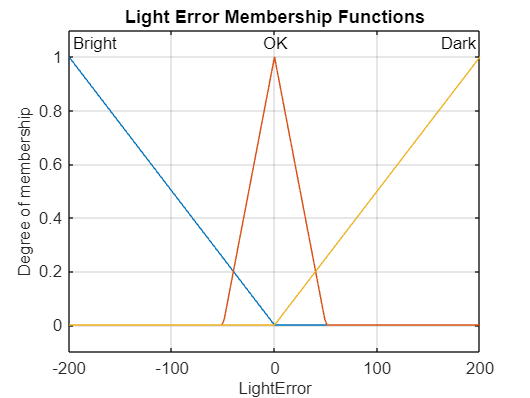

figure
plotmf(fisL,'input',1)
title('Light Error Membership Functions')
grid on

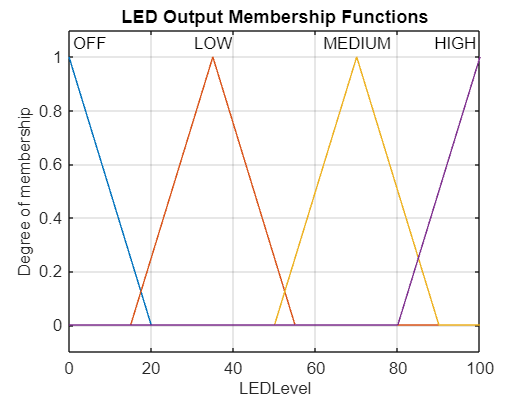


figure
plotmf(fisL,'output',1)
title('LED Output Membership Functions')
grid on

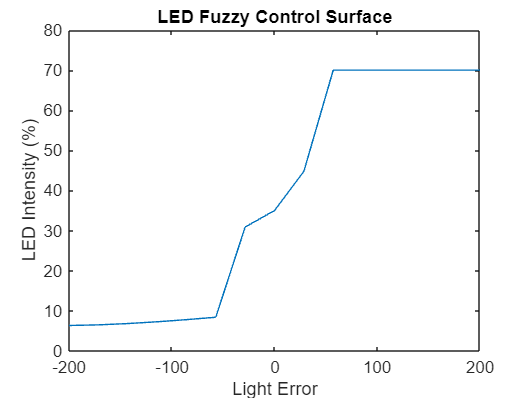


figure
gensurf(fisL)
xlabel('Light Error')
ylabel('LED Intensity (%)')
title('LED Fuzzy Control Surface')